# **Lab 8. Dynamic system identification using neural networks**

Through this lab we will train a neural network in order to approximate a non-linear dynamic system. We will choose a proper input signal for the neural network in order to evaluate the goodness of the results.

## 1. Generating the dynamic system

Before creating and training our neural network, we need to define the dynamic system we want to approximate.

clc, clearvars, close all

### 1.1. Defining the external dynamics

We can define a MATLAB function that implements the system.

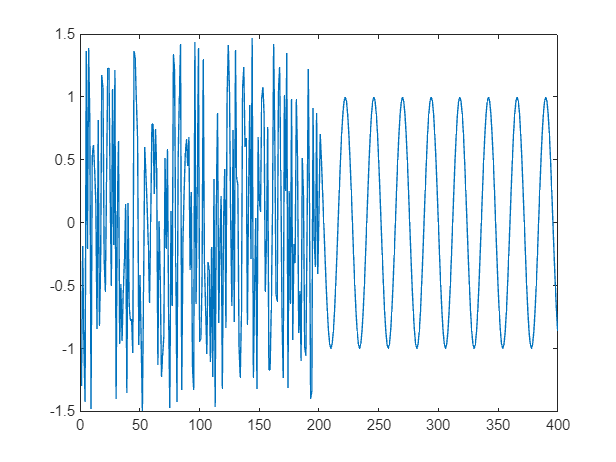

function [y] = f(y1,y2)
    % Behaviour of the system
    y = (y1*y2*(y1-0.5))/(1+(y1^2)*y2^2);
end

It's important to see that this function only depends from the previous values of the output:


$$y\left(k\right)=f\left\lbrack y\left(k-1\right),y\left(k-2\right)\right\rbrack +u\left(k\right)$$


### 1.2. Defining the identification input

We suppose that the system we just defined has an input that changes over time. We consider a total amount of 400 samples and we build an input vector so that for the first half of the samples the input is white noise and for the second half the input is a sine.

% Input vector
u = [3*(rand(1,200)-0.5), sin(2*pi*(201:400)/24)];

To better understand the shape of the input signal, we plot it.

% Plotting input signal
figure(1), plot(u)

### 1.3. Defining the system to identify

Given the input vector we can compute the outputs of the system we want to identify. Since the output depends from the history of the system, we have to keep in mind that for the first two time instants the output of the system will only depend from the input. In fact:


$$y\left(1\right)=f\left(0,0\right)+u\left(1\right)=u\left(1\right)$$


because for $k=1$ the previous values of the output $y\left(k-1\right)$ and $y\left(k-2\right)$ are not defined and so are considered equal to zero.

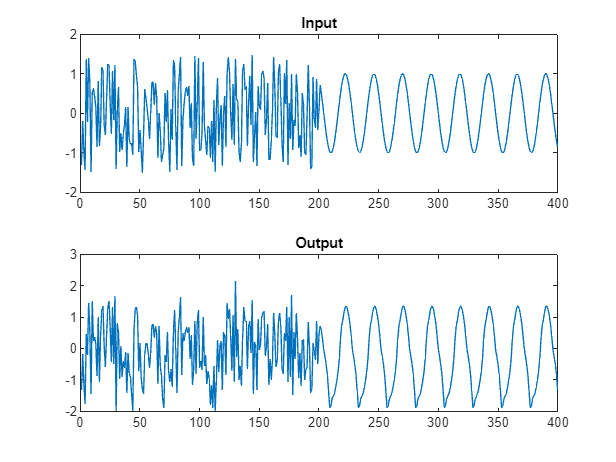

% Output vector
y = zeros(1,400);

% First two outputs
y(1) = u(1);
y(2) = u(2);

% System dynamics
for k=3:length(y)

    % Computing output
    y(k) = f(y(k-1),y(k-2)) + u(k);
end

Once we computed the output of the non-linear system, we can plot it to better understand its behaviour.

% Plotting output
figure(2),
subplot(2,1,1), plot(u), title("Input"),
subplot(2,1,2), plot(y), title("Output");

As we can see the output of the system has not exactly the same shape of the input as the system introduces some form of distortion.

## 2. Using the neural network

We will use a neural network in order to learn the non-linear behaviour of the system.

### 2.1. Defining the training data

The output of the non-linear system depends from the previous history of the system through the values $y\left(k-1\right)$, $y\left(k-2\right)$ and $u\left(k\right)$. These variables will represent the training inputs of the neural network, which we can define as a matrix where:

- the first row will contain the output delayed by one step (the first element will be equal to zero);

- the second row will contain the output of the system delayed by two steps (the first two elements will be equal to zero);

- the third row will contain the input to the system.

% Input declaration
trainingInput = zeros(3,400);

% Input initialization
trainingInput(1,:) = [0, y(1:399)];
trainingInput(2,:) = [0, 0, y(1:398)];
trainingInput(3,:) = u;

Once the training inputs have been declared, we can also consider the training output as the output of the non-linear system.

% Output
trainingOutput = y;

We want the neural network to learn how, given the inputs, the non-linear system gave back the outputs. In other words, we want our neural network to learn how to properly approximate the non-linear relationship that allows to compute the output.

### 2.2. Defining the neural network

In order to define a neural network, we need to use the command `feedforwardnet`. This command will create a neural network with a Multi-Layer Perceptron (MLP) architecture. We need to specify the number of neurons for each of the considered hidden layers.

% Neural network
net = feedforwardnet([5,5]);

### 2.3. Training the neural network

Now we train our neural network using the backpropagation algorithm. MATLAB will automatically split the dataset in three parts.

- Training set: data used to determine the optimal weights of the neural network with the training algorithm.

- Validation set: data used to evauate the training process of the neural network through the computation of the Mean Squared Error (MSE) for each epoch. If this index increases, the training process will stop to avoid the overtraining phenomena.

- Test set: data used for similar purposes of the validation set, but the training does not stop.

We define a new neural network that will have the optimal parameters computed by the training algorithm. In this way we can preserve the original parameters of the network without overwriting them.

% Training the neural network
trainedNet = train(net,trainingInput,trainingOutput);

### 2.4. Computing predictions

After the training of the neural network, we can compute its output starting from the inputs in order to see how well it has learned.

% Neural network output
ynet = sim(trainedNet,trainingInput);

Now we can compute the prediction error as the difference between the training output and the prediction output.

% Prediction error
ep = trainingOutput - ynet;

and then we can also plot the differences.

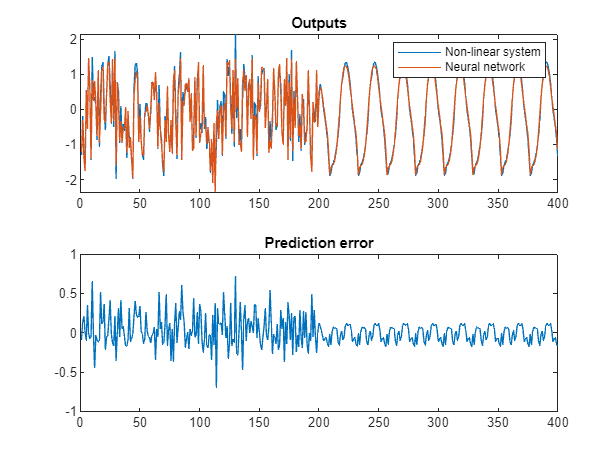

% Comparison between outputs
figure(3),
subplot(2,1,1), plot(trainingOutput), hold on, plot(ynet),

legend("Non-linear system","Neural network"), title("Outputs"),
subplot(2,1,2), plot(ep), title("Prediction error");

As we can see the neural network has properly learned the non-linear behaviour of the system.

## 3. Validating the neural network

After the training process we expect our neural network to be able to approximate the behaviour of the system for a given input.

### 3.1. Defining an APRBS input

One particular class of input signals that we can use to explore the non-linearity domain is the Amplitude Pseudo-Random Binary Signals (APRBS), which are an extension of the Pseudo-Random Binary Signals (PRBS) by introducing amplitude modulation.

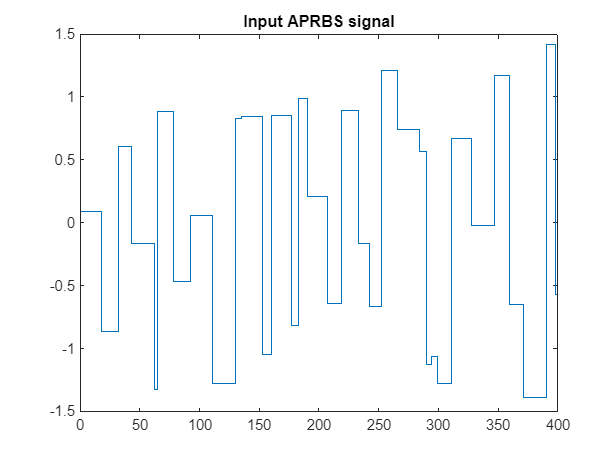

function u = aprbs(N,Tmin,Tmax,Vmin,Vmax)
    
    % Initialization

    L = round(Tmin + (Tmax-Tmin)*rand(1));
    u = (Vmin + (Vmax-Vmin)*rand(1))*ones(1,L);
    i = L;

levels = 33


    % APRBS signal
    while(i<N)
        L = round(Tmin +(Tmax-Tmin)*rand(1));
        if ((i+L) <= N)
            q=(Vmin + (Vmax-Vmin)*rand(1))*ones(1,L);
        else
            q=(Vmin + (Vmax-Vmin)*rand(1))*ones(1,N-i);
        end
        u = [u,q];
        i = i+L;
    end
end

In paticular we define the following APRBS signal.

% Input vector
U = aprbs(400,1,20,-1.5,1.5);

To better understand the shape of this signal, we can plot it.

figure(4), stairs(U), title("Input APRBS signal");

It is quite an interesting signal because it has a good variability in amplitude but has an hold time that can help evaluate the equilibrium points of the non-linear system. We can determine the number of unique amplitude levels in this way:

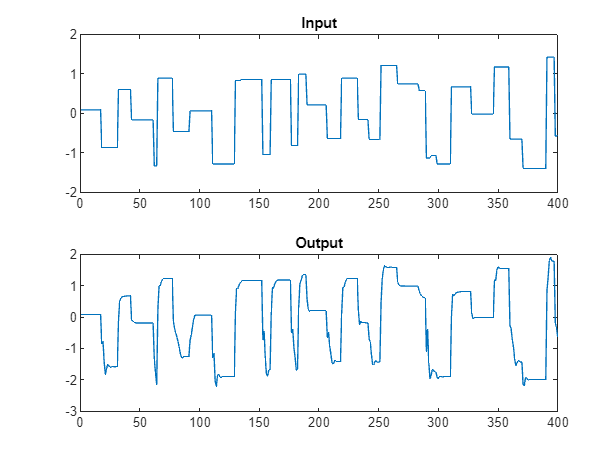

% Amplitude levels

levels = numel(unique(U))

### 3.2. Computing the output of the system

Given this new input signal, we can compute the output of the non-linear system.

% Output vector
Y = zeros(1,400);

% First two outputs
Y(1) = U(1);
Y(2) = U(2);

% System dynamics
for k=3:length(Y)

    % Computing output
    Y(k) = f(Y(k-1),Y(k-2)) + U(k);
end

Once we computed the output of the non-linear system, we can plot it to better understand its behaviour.

% Plotting output
figure(5),
subplot(2,1,1), plot(U), title("Input"),
subplot(2,1,2), plot(Y), title("Output");

### 3.3. Computing prediction error

Since we trained our neural network, we expect it to perform well also with the APRBS signal. By the way, in this case we need to define a new input matrix for our neural network since the input signal has changed. We still consider the same structure.

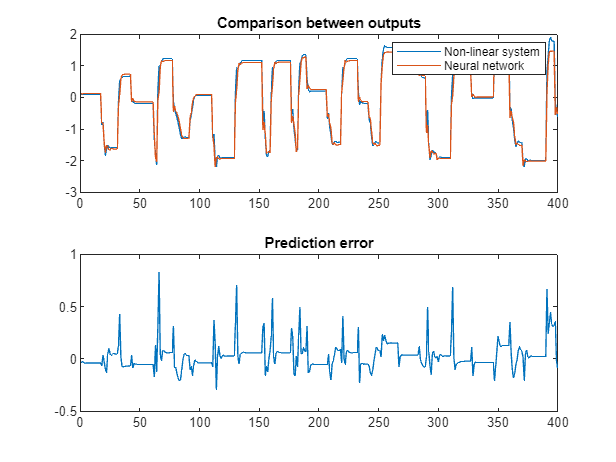

% Input declaration
predictionInput = zeros(3,400);


% Input initialization
predictionInput(1,:) = [0, Y(1:399)];
predictionInput(2,:) = [0, 0, Y(1:398)];
predictionInput(3,:) = U;

Now we can compute the predictions of the neural network.

% Neural network output
predictionOutput = sim(trainedNet,predictionInput);

Now we can compute the prediction error as the difference between the output of the system and the predicted output.

% Prediction error
ep = Y - predictionOutput;

and then we can also plot the differences.

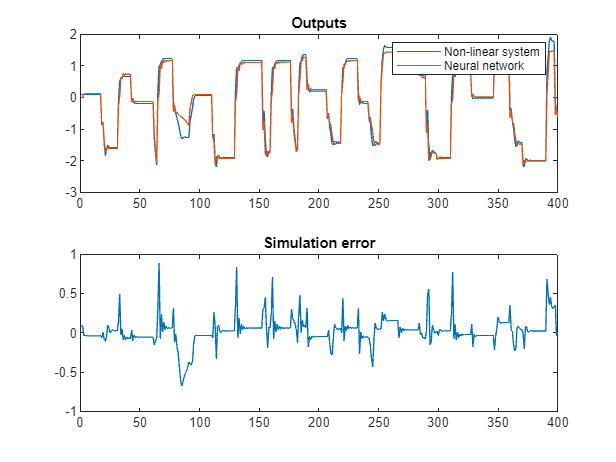

% Comparison between outputs
figure(6),
subplot(2,1,1), plot(Y), hold on, plot(predictionOutput), 
legend("Non-linear system","Neural network"),
title("Comparison between outputs"),

subplot(2,1,2), plot(ep), title("Prediction error");

As we can see the results of the neural network are accurate, meaning that it has learned properly the behaviour of the system.

### 3.4. Computing the simulation error

By closing our neural network in a feedback loop, we obtain a simulator. In other words the output of the neural network will be based on the previous values of the simulation output. Since the input matrix will not depend from the history of the system anymore, we define a new input matrix where the first row will contain the simulation output delayed by one step, the second row will contain the simulation output delayed by two steps and the third row will contain the input vector.

% Initialization
simulationOutput = zeros(1,400);

Now we can compute the output of the simulation.

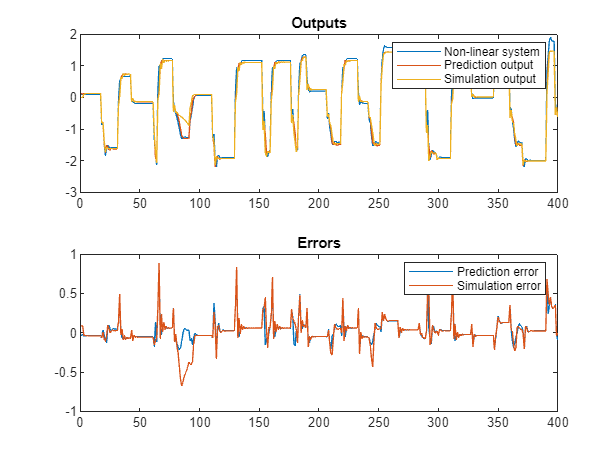

% Simulated output
for k=3:400
    simulationOutput(k) = sim(trainedNet, [simulationOutput(k-1); simulationOutput(k-2); U(k)]);
end

Now we can compute the simulation error as the difference between the output of the system and the simulation output.

% Prediction error
es = Y - simulationOutput;

and then we can also plot the differences.

% Comparison between outputs
figure(7),
subplot(2,1,1), plot(Y), hold on, plot(simulationOutput), 
legend("Non-linear system","Neural network"), title("Outputs"),
subplot(2,1,2), plot(es), title("Simulation error");

### 3.5. Comparing errors

In order to understand the difference between the prediction error and the simulation error we compare them through a plot.

figure(8),
subplot(2,1,1), plot(Y), hold on, plot(predictionOutput), hold on, plot(simulationOutput),
legend("Non-linear system","Prediction output","Simulation output"), title("Outputs"),
subplot(2,1,2), plot(ep), hold on, plot(es),
legend("Prediction error","Simulation error"), title("Errors");

As we can see the simulation error seems to be worse than the prediction error because of the simulation output, since is not directly measurable, is affected by errors that tend to diverge and cause instability.